# VIT (vision Transformer)

#### **Fred liu 2024.02.20**

**Load ViT Model**

[net,classNames] = visionTransformer;

View the neural network.

net

net =   dlnetwork with properties:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [167×2 table]
     Learnables: [200×3 table]
          State: [0×3 table]
     InputNames: {'imageinput'}
    OutputNames: {'softmax'}
    Initialized: 1

  View summary with summary.


View the number of classes.

numClasses = numel(classNames)

numClasses = 1000

**Inference**

img = imread("bunny02.jpg");
img = imresize(img,[384 384]);

predict & one hotdecode

output = predict(net,single(img));
label = onehotdecode(output,classNames,2);

show Img

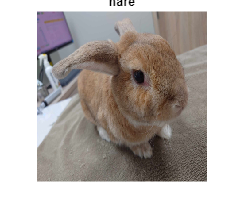

imshow(img)
title(label)

Training

imds = imageDatastore("Dog_Images\",IncludeSubfolders=true,LabelSource="foldernames");

visual class

classNames = categories(imds.Labels)

classNames = 3×1 cell array
    {'Chihuahua'       }
    {'Japanese_spaniel'}
    {'Maltese_dog'     }


numClasses = numel(categories(imds.Labels))

numClasses = 3

split data

[imdsTrain,imdsValidation,imdsTest] = splitEachLabel(imds,0.8,0.1);

DataAugmenter

augmenter = imageDataAugmenter( ...
    RandXReflection=true, ...
    RandRotation=[-90 90], ...
    RandScale=[1 2]);
inputSize = net.Layers(1).InputSize

inputSize =    384   384     3


augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,DataAugmentation=augmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

Load Model

[VisionNet,VisionNetclass] = visionTransformer("base-16-imagenet-384");
analyzeNetwork(VisionNet)

抽換fullyconnected(改成對應的分類數量)

layer = fullyConnectedLayer(numClasses,Name="head");
VisionNet_re = replaceLayer(VisionNet,"head",layer);

Training Options

miniBatchSize = 12;

numObservationsTrain = numel(augimdsTrain.Files);
numIterationsPerEpoch = floor(numObservationsTrain/miniBatchSize);

options = trainingOptions("adam", ...
    MaxEpochs=4, ...
    InitialLearnRate=0.0001, ...
    MiniBatchSize=miniBatchSize, ...
    ValidationData=augimdsValidation, ...
    ValidationFrequency=numIterationsPerEpoch, ...
    OutputNetwork="best-validation-loss", ...
    Plots="training-progress", ...
    Metrics="accuracy", ...
    Verbose=false);

Train

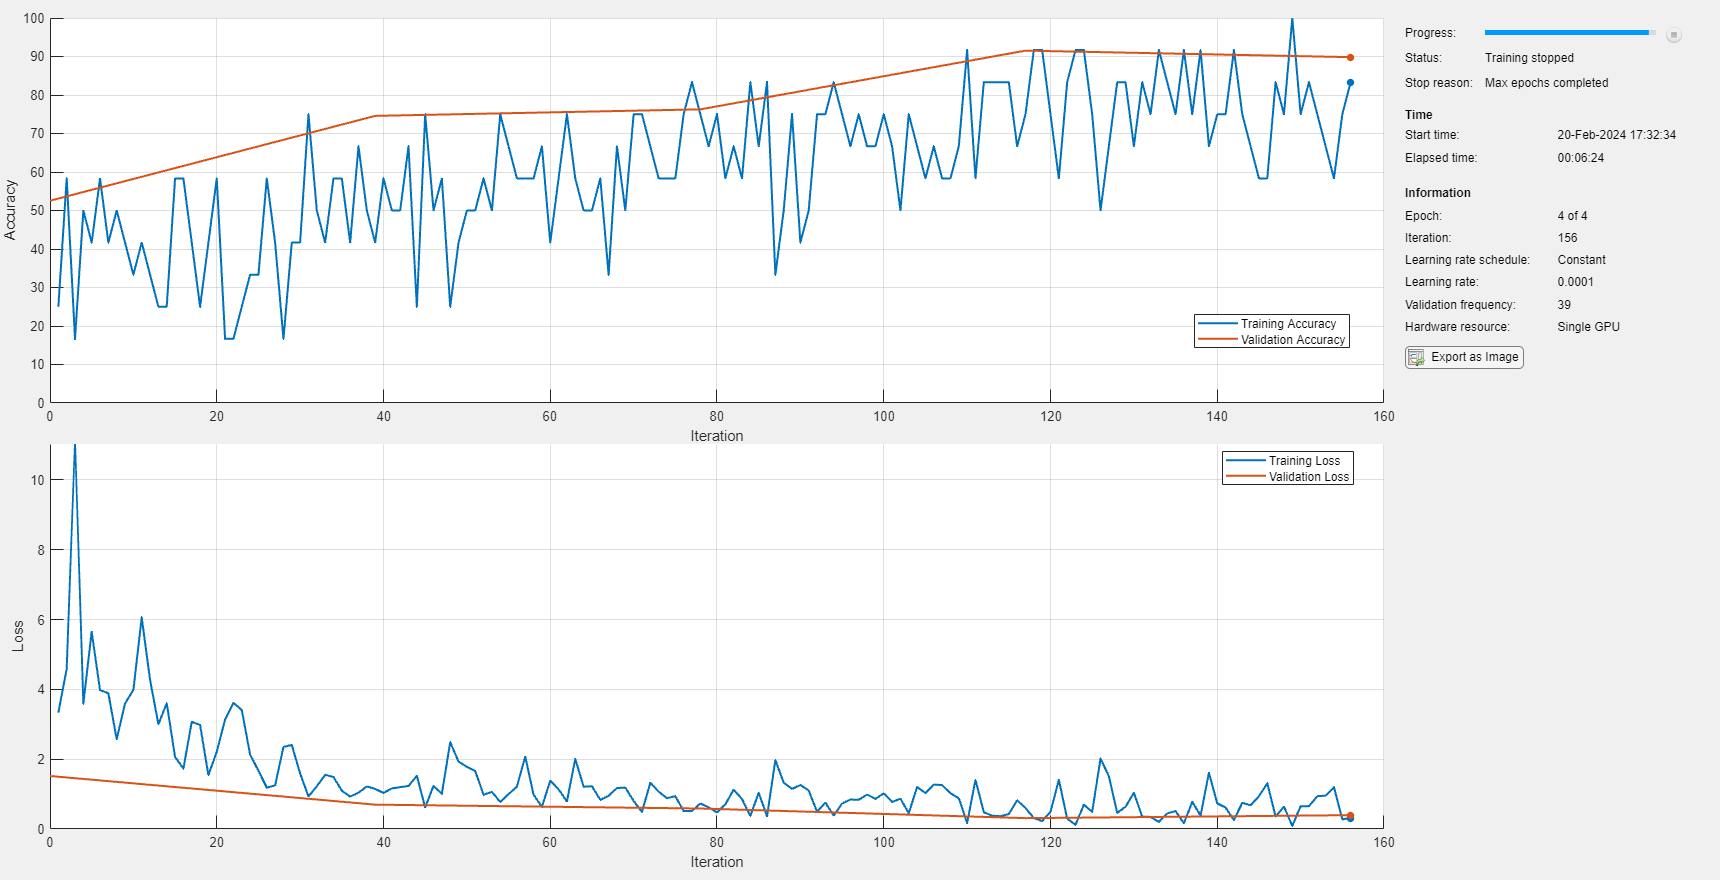

net = trainnet(augimdsTrain,VisionNet_re,"crossentropy",options);

Test Data

mbq = minibatchqueue(augimdsTest,1, ...
    MiniBatchFormat="SSCB");

YTest = [];

% Loop over mini-batches.
while hasdata(mbq)
    
    % Read mini-batch of data.
    X = next(mbq);
       
    % Make predictions using the predict function.
    Y = predict(net,X);
   
    % Convert scores to classes.
    predBatch = onehotdecode(Y,classNames,1);
    YTest = [YTest; predBatch'];
end

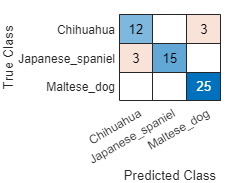

figure
TTest = imdsTest.Labels;
confusionchart(TTest,YTest)